Let's design a controller for the following system:

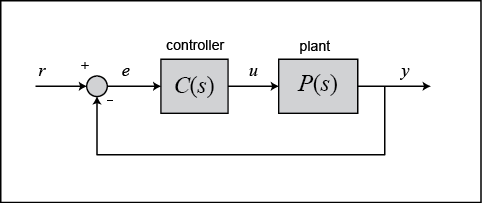

Where $C(s)$ is the controller and $P(s)$ is the transfer function of the Plant.

The canonical form of the second-order differential equation in the time domain is as shown in the following:


$$ 
\frac{1}{\omega_0^2} \ddot{y} + \frac{2D}{\omega_0}\ \dot{y} + y = Ku(t) \quad \textrm{or} \ \quad \ddot{y} + 2D\omega_0 \dot{y} + \omega_0^2 y = K\omega_0^2 u
$$


The canonical second-order transfer function has the following form, in which it has two poles and no zeros.


$$ 
G(s) = \frac{K \omega_0^2}{s^2 + 2D\omega_0 s + \omega_0^2}
$$


w_0 = 10

w_0 = 10

D = 25

D = 25

K = 6;
s = tf('s');
G = K*w_0/(s^2 + 2*D*w_0*s + w_0^2)

G =
 
         60
  -----------------
  s^2 + 500 s + 100
 
Continuous-time transfer function.



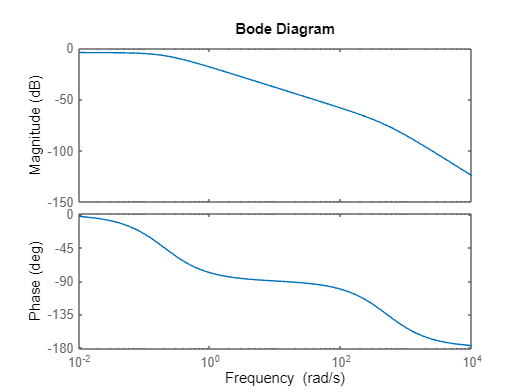

bode(G)

Poles = pole(G)

Poles =  -499.7999
   -0.2001


Kp = 350;
Ki = 300;
Kd = 50;
C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 350, Ki = 300, Kd = 50
 
Continuous-time PID controller in parallel form.



T = feedback(C*G,1)

T =
 
     3000 s^2 + 21000 s + 18000
  --------------------------------
  s^3 + 3500 s^2 + 21100 s + 18000
 
Continuous-time transfer function.



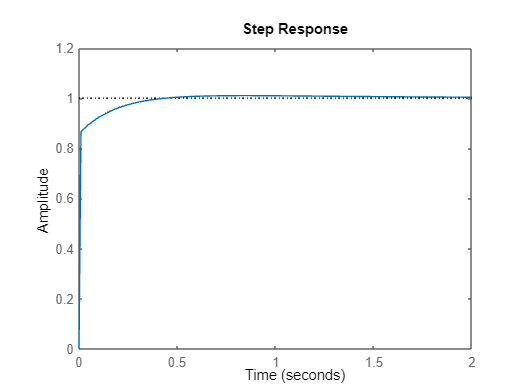

t = 0:0.01:2;

step(T,t)

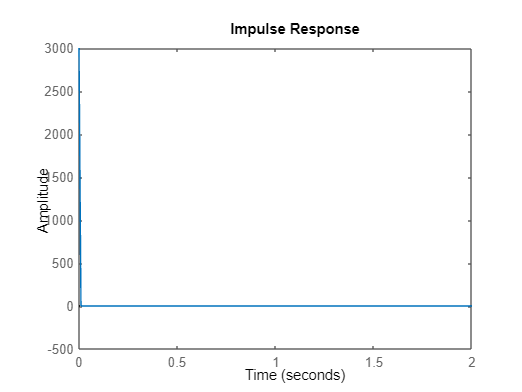

impulse(T,t)

%pidTuner(G,'PID')

% In case of a need of a system identification Tool:
%ident